# `Actividad 3.2 (Trayectorias en lazo abierto)`

### `Objetivo: `

`Implementar `el código requerido para generar 1 de la siguiente figura, empleando trayectorias a partir de las velocidades angular y lineal en un plano 2D.

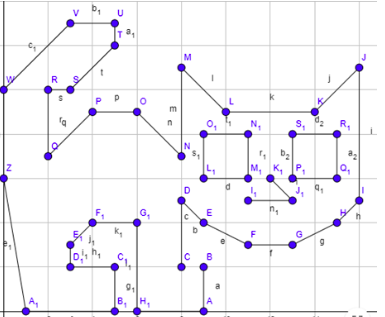

### Procedimiento:

Para empezar, se consiguió la figura diseñada en geogebra, y con la misma herramienta se obtuvieron los ángulos y longitudes de las rectas. Los ángulos que se muestran no son los ángulos reales que el robot tiene que girar, para obtener el ángulo real se hace una resta de 180° - grados que se marca en verde.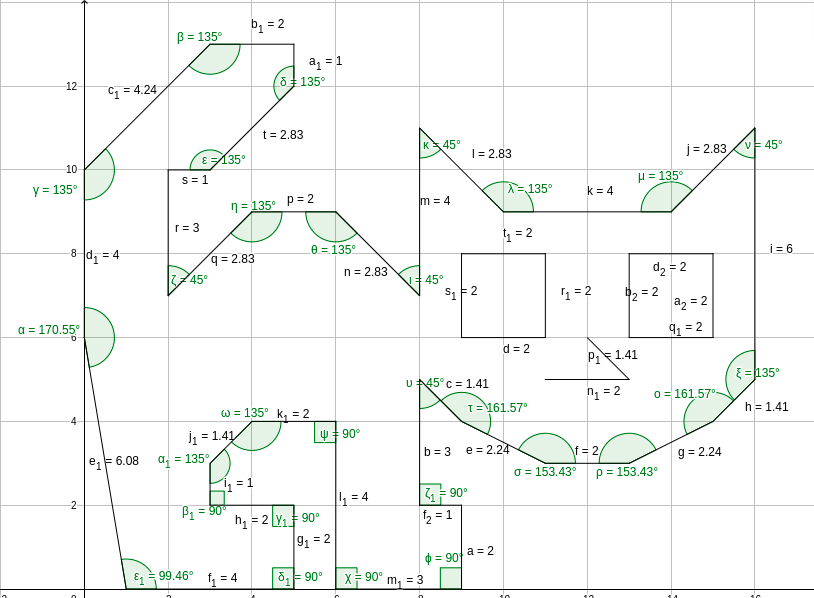

Se hace una limpieza de pantalla y del workspace

%Limpieza de pantalla
clear all
close all
clc

Se definen las variables para nuestro tiempo de simulación como tiempo final de la simulacion, tiempo de muestreo, vector de tiempo y el número de muestras.

Tiempo final: Es el tiempo total de simulación, este es la suma total del tiempo que nuestro robot avanzara en linealmente y angularmente, en una sección 

Tiempo de muestreo: Es cada cuanto tiempo nuestro robot va a estar en una nueva posicion.

Vector de tiempo: Va de 0 al tiempo final de nuestra simulación, en incrementos de nuestro tiempo de muestreo.

Número de muestras: Es el número total de pasos que dará nuestro robot.

%%%%%%%%%%%%%%%%%%%%%%%%% TIEMPO %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
tf=112.2;             % Tiempo de simulación en segundos (s)
ts=0.1;            % Tiempo de muestreo en segundos (s)
t=0:ts:tf;         % Vector de tiempo
N= length(t);      % Muestras


En esta parte se declaran e inicializan con ceros nuestros vectores de coordenadas (x, y) y el vector del ángulo y con una longitud del número de pasos de nuestro robot, mas una muestra más por la integral de euler.

También se declara que la posición inicial de nuestro robot va a ser la que aparece en la imagen de geogebra, que es (0,6) con un ángulo de -80.55°

%%%%%%%%%%%%%%%%%%% CONDICIONES INICIALES %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%Inicializamos las variables que se van a emplear
x1= zeros (1, N+1);       % Posición (X) en el centro del eje que une las ruedas en metros (m)
y1= zeros (1, N+1);       % Posición (Y) en el centro del eje que une las ruedas en metros (m)
phi= zeros (1, N+1);      % Orientación del robot en radiaanes (rad)

%Damos valores a nuestro punto inicial de posición y orientación
x1(1)=0;  %Posición inicial eje x
y1(1)=6;  %Posición inicial eje y
phi(1)=deg2rad(-80.55); %Orientación inicial del robot 

Del mismo modo se inicializa nuestro punto de control con zeros con una longitud de las N muestras. Su coordenada inicial será la misma que la del robot.

%%%%%%%%%%%%%%%%%%%%% PUNTO DE CONTROL %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%Inicializamos el punto de control 
hx= zeros (1, N+1);       % Posición en el eje (X) del punto de control en metros (m)
hy= zeros (1, N+1);       % Posición en el eje (Y) del punto de control en metros (m)

%Igualamos el punto de control con las proyecciones X1 y Y1 por su
%coincidencia
hx(1)= x1(1);       % Posición del punto de control en el eje (X) metros (m)
hy(1)= y1(1);       % Posición del punto de control en el eje (Y) metros (m)

Ahora se inicializan nuestros vectores de velocidades lineales y velocidades angulares. Para esto se inicializa nuestro vector de velocidad lineal con 1's y nuestro vector de velocidades angulares con 0's, ya que como nuestro robot la mayor parte del tiempo girara en línea recta, después solo se modifican los vectores en  las muestras en las que el robot tiene que girar.

%%%%%%%%%%%%%%%%%%%%%% VELOCIDADES DE REFERENCIA %%%%%%%%%%%%%%%%%%%%%%%%%%

v = 1*ones(1,N); % Velocidad lineal de referencia (m/s)
w = 0*ones(1,N); % Velocidad angular de referencia (rad/s)

En un principio se modificaron los velocidades lineales y angulares siguiendo la siguiente metodología: Tomando como referencia que un giro de 90° en 1 segundo (10 muestras), si se deseaban girar 80.54°, se hacía una regla de 3 para obtener el número de muestras que debían de ser modificadas, y a esas muestras se cambiaba la velocidad angular con el ángulo que queremos girar usando la función predeterminada de matlab para convertir de grados a radianes. Así mismo, en las mismas muestras de la velocidad lineal se  definen como 0.

v(61:70) = 0;
w(61:70) = deg2rad(80.54); 

v(111:120) = 0;
w(111:120) = deg2rad(90); 


v(141:150) = 0;
w(141:150) = deg2rad(90);


v(171:180) = 0;
w(171:180) = deg2rad(-90);

v(191:200) = 0;
w(191:200) = deg2rad(-45);

v(215:224) = 0;
w(215:224) = deg2rad(-45);

v(246:254) = 0;
w(246:255) = deg2rad(-90);

v(295:304) = 0;
w(295:304) = deg2rad(90);

v(335:344) = 0;
w(335:344) = deg2rad(90);

v(365:374) = 0;
w(365:374) = deg2rad(90);

v(385:394) = 0;
w(385:394) = deg2rad(-90);

Sin embargo, después de un rato se noto que se podía hacer de otra manera más correcta y se procedió a hacerlo de esa manera.

Como se mencionó anteriormente, Sabiendo que un giro de 90° se concreta en 1 segundo = 10 muestras,  lo que es igual a 1° = 0.1111 muestras. Por lo tanto, si se quieren girar 135° se multiplicaba el número de grados por su equivalente en muestras (135°x0.11111), dando como resultado el número de muestras que se debían girar a la velocidad de 90°/s para llegar al mismo ángulo (135°)

v(425:439) = 0;
w(425:439) = deg2rad(-90);

v(455:456) = 0;
w(455:456) = deg2rad(90);

v(482:484) = 0;
w(482:484) = deg2rad(90);

v(505:507) = 0;
w(505:507) = deg2rad(90);

v(530:532) = 0;
w(530:532) = deg2rad(90);

v(545:548) = 0;
w(545:548) = deg2rad(90);

v(609:623) = 0;
w(609:623) = deg2rad(90);

v(652:656) = 0;
w(652:656) = deg2rad(-90);

v(697:701) = 0;
w(697:701) = deg2rad(-90);

v(730:744) = 0;
w(730:744) = deg2rad(90);

v(785:799) = 0;
w(785:799) = deg2rad(-90);

v(828:832) = 0;
w(828:832) = deg2rad(90);

v(853:857) = 0;
w(853:857) = deg2rad(90);

v(886:900) = 0;
w(886:900) = deg2rad(-90);

v(931:940) = 0;
w(931:940) = deg2rad(-90);

v(951:955) = 0;
w(951:955) = deg2rad(90);

v(984:988) = 0;
w(984:988) = deg2rad(90);

v(999:1008) = 0;
w(999:1008) = deg2rad(90);

v(1028:1033) = 0;
w(1029:1033) = deg2rad(90);

v(1079:1083) = 0;
w(1079:1083) = deg2rad(90);


Y para finalizar solo se hace la simulación del robot haciendo la trayectoria, en un ciclo for del número de muestras y usando funciones de código externo proporcionado por el profesor.

En el mismo bucle se calcula el ángulo phi y las posiciones siguientes del robot mediante el método de euler. 

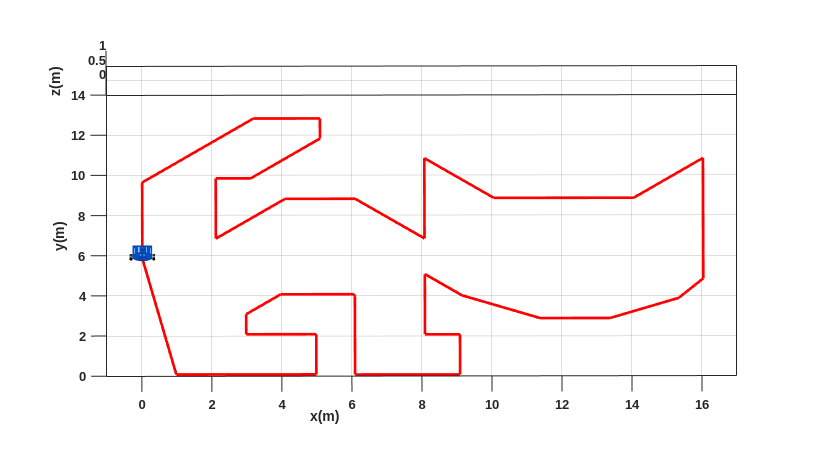


%%%%%%%%%%%%%%%%%%%%%%%%% BUCLE DE SIMULACION %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

for k=1:N 

    %Aplico la integral a la velocidad angular para obtener el angulo "phi" de la orientación
    phi(k+1)=phi(k)+w(k)*ts; % Integral numérica (método de Euler)
           
   %%%%%%%%%%%%%%%%%%%%% MODELO CINEMATICO %%%%%%%%%%%%%%%%%%%%%%%%%
    
    xp1=v(k)*cos(phi(k)); 
    yp1=v(k)*sin(phi(k));
 
    %Aplico la integral a la velocidad lineal para obtener las cordenadas
    %"x1" y "y1" de la posición
    x1(k+1)=x1(k)+ ts*xp1; % Integral numérica (método de Euler)
    y1(k+1)=y1(k)+ ts*yp1; % Integral numérica (método de Euler)

    % Posicion del robot con respecto al punto de control
    hx(k+1)=x1(k+1); 
    hy(k+1)=y1(k+1);

end


%%%%%%%%%%%%%%%%%%%%%%%%%%%%% SIMULACION VIRTUAL 3D %%%%%%%%%%%%%%%%%%%%%%%%%%%%

% a) Configuracion de escena

scene=figure;  % Crear figura (Escena)
set(scene,'Color','white'); % Color del fondo de la escena
set(gca,'FontWeight','bold') ;% Negrilla en los ejes y etiquetas
sizeScreen=get(0,'ScreenSize'); % Retorna el tamaño de la pantalla del computador
set(scene,'position',sizeScreen); % Configurar tamaño de la figura
camlight('headlight'); % Luz para la escena
axis equal; % Establece la relación de aspecto para que las unidades de datos sean las mismas en todas las direcciones.
grid on; % Mostrar líneas de cuadrícula en los ejes
box on; % Mostrar contorno de ejes
xlabel('x(m)'); ylabel('y(m)'); zlabel('z(m)'); % Etiqueta de los eje

view([-0.1 35]); % Orientacion de la figura
axis([-1 17 0 14 0 1]); % Ingresar limites minimos y maximos en los ejes x y z [minX maxX minY maxY minZ maxZ]

% b) Graficar robots en la posicion inicial
scale = 4;
MobileRobot;
H1=MobilePlot(x1(1),y1(1),phi(1),scale);hold on;

% c) Graficar Trayectorias
H2=plot3(hx(1),hy(1),0,'r','lineWidth',2);

% d) Bucle de simulacion de movimiento del robot

step=1; % pasos para simulacion

for k=1:step:N

    delete(H1);    
    delete(H2);
    
    H1=MobilePlot(x1(k),y1(k),phi(k),scale);
    H2=plot3(hx(1:k),hy(1:k),zeros(1,k),'r','lineWidth',2);
    
    pause(ts);

end